Multi-Fidelity GP model

Takes a list of GPs as an input and a mean function and a kernel object

A = 0.5; B = 10; C = -5;
ff{1} = @(x) (6*x-2).^2.*sin(12*x-4);
ff{2} = @(x) 0.4*ff{1}(x)-x-1;
ff{3} = @(x) A*ff{1}(x)+B*(x-0.5)-C; 

xx = linspace(0,1,100)';
yy = ff{1}(xx);


x{1} = [0;0.65;1];
y{1} = ff{1}(x{1});

for i = 2:3
x{i} = [x{i-1}; lhsdesign(5,1)];
y{i} = ff{i}(x{i});
end

ma = means.linear(4) + means.const(1);
mb = means.linear(2);%*means.sine(1,10,0,1);

a = kernels.Matern52(1,0.2);%.periodic(1,10);
b = kernels.EQ(1,0.3);
a.signn = eps;
b.signn = eps;

tic
for i = 1:3
    Z{i} = GP(mb,b);
    Z{i} = Z{i}|[x{i} y{i}];
    Z{i} = Z{i}.train();
end
toc

Elapsed time is 0.710550 seconds.


tic
MF = MFGP(Z,ma,a);
MF = MF.condition(Z);
MF = MF.train();
toc

Elapsed time is 1.104844 seconds.


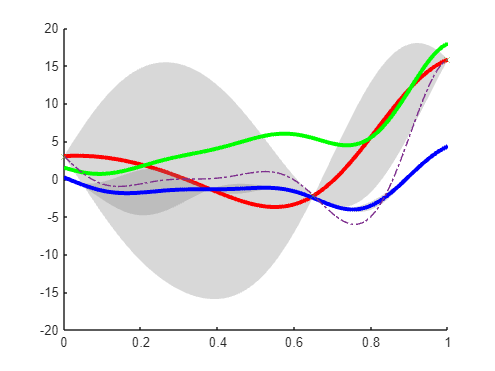

figure
hold on
utils.plotLineOut(Z{1},1,1,'color','r')
utils.plotLineOut(Z{2},1,1,'color','b')
utils.plotLineOut(Z{3},1,1,'color','g')
plot(xx,yy,'-.')
plot(x{1},y{1},'x')

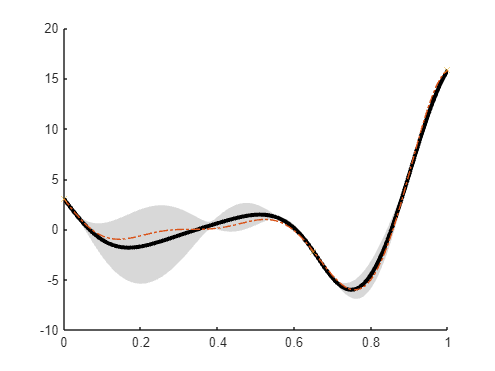

figure
hold on
utils.plotLineOut(MF,1,1)
plot(xx,yy,'-.')
plot(x{1},y{1},'x')

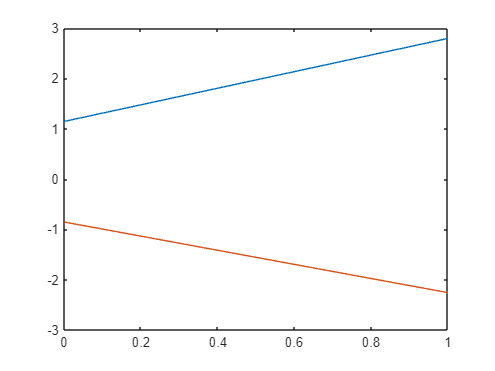

ym2 = MF.Zd{2}.mean.eval(xx);
ym3 = MF.Zd{3}.mean.eval(xx);

figure
plot(xx,ym2)
hold on
plot(xx,ym3)

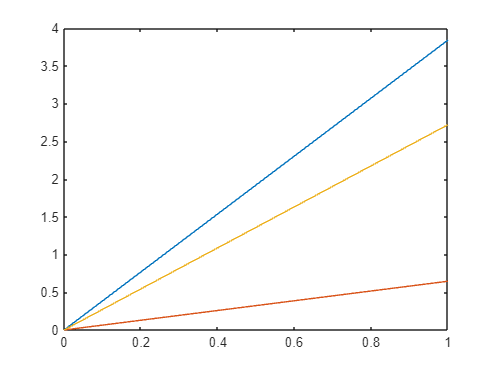


ym1 = MF.GPs{1}.mean.eval(xx);
ym2 = MF.GPs{2}.mean.eval(xx);
ym3 = MF.GPs{3}.mean.eval(xx);


figure
plot(xx,ym1)
hold on
plot(xx,ym2)
plot(xx,ym3)

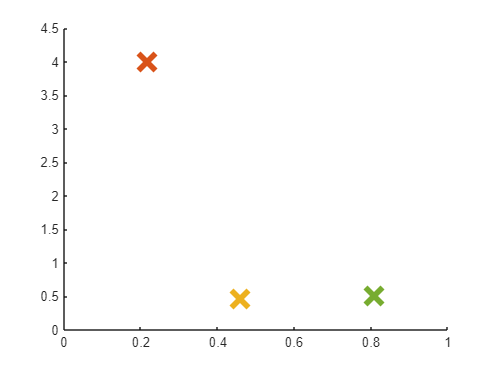

figure
hold on
tic
for i = 1:5
    [x{i},R{i}] = BO.argmax(@BO.maxVAR,MF);
    plot(x{i},R{i},'x','MarkerSize',18,'LineWidth',4)
end
xlim([0 1])

toc

Elapsed time is 1.615456 seconds.


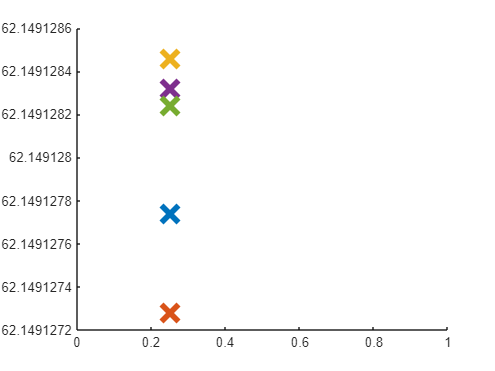


figure
hold on
tic
for i = 1:5
    [x{i},R{i}] = BO.argmax(@BO.MFSFDelta,MF);
    plot(x{i},R{i},'x','MarkerSize',18,'LineWidth',4)
end
xlim([0 1])

toc

Elapsed time is 2.476243 seconds.
